# Bitcoin price example

clear
addpath(fullfile('..'));
addpath(fullfile('..','src'));
addpath(fullfile('..','src','figs'));

## Reading data

file = fullfile('..','data','BTC.txt');
BTC = readtable(file);     % Reading data as table object
raw = BTC.Close/1e4;       % Serie data array
time = BTC.Date;           % Time as datetime objec

## Monte-Carlo Simulation

%snrr = snr(raw);           % Signal to noise ratio
snrr = 70;
n = 1000;                  % Number of MC symulations

wbh = waitbar(0,'0%','Name',strcat('Adding White Noise with snr=',num2str(snrr,'%2.1f'),'%'));
serie = [];
for i = 1:n
    serie = cat(2,serie,awgn(raw,snrr,'measured'));
    wtr = i/n;
    waitbar(wtr,wbh,strcat(num2str(wtr*100,'%3.0f'),'%'));
end
close(wbh)

## Computing the EEMD

opt = 'pchip';             % Interpolating method
d = EMD_timeseries(time, serie, opt);

## Plotting IMFs

close all
plot_timeseries(d);


## Significance of IMFs

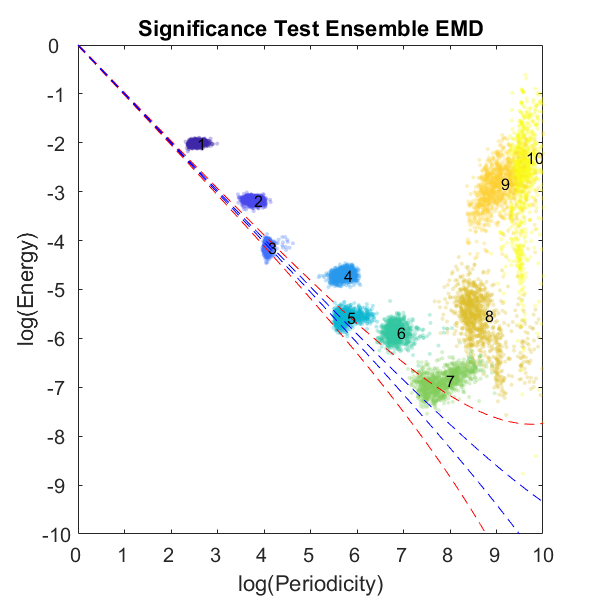

close all
plot_sign(d,'Significance Test Ensemble EMD','-no');